# Final Project

## Infor infor

xxx-xxx-xxx

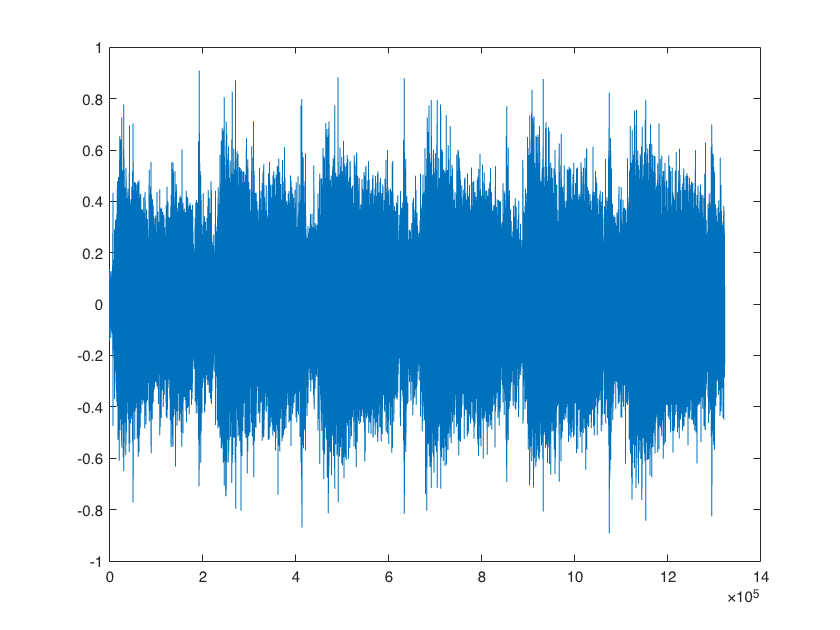

[x,fs] = audioread('../noisy.wav');
plot(x);

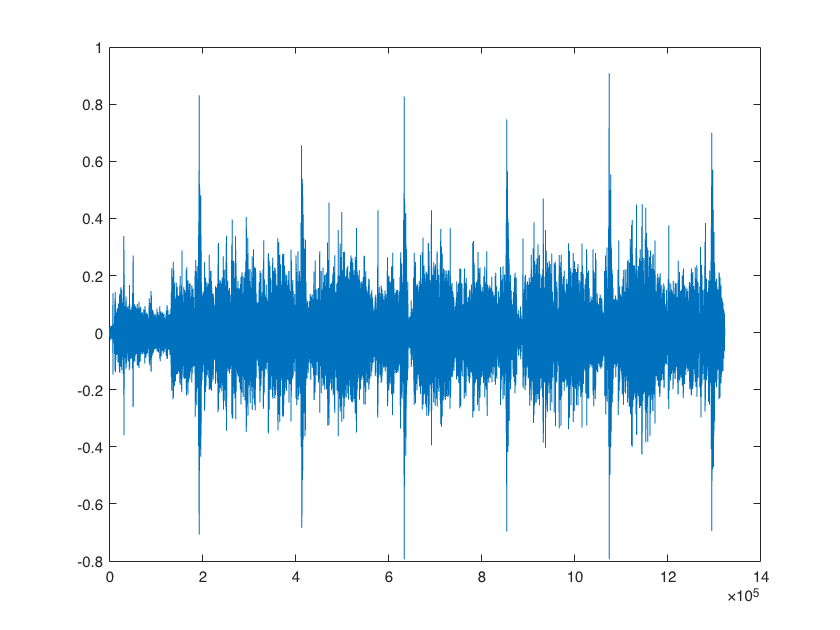

xhat = denoise(x, fs);
plot(xhat);

[cleanSig, fs] = audioread('../clean.wav');
result_snr = computeSnr(cleanSig, xhat)

ans = 2.0776

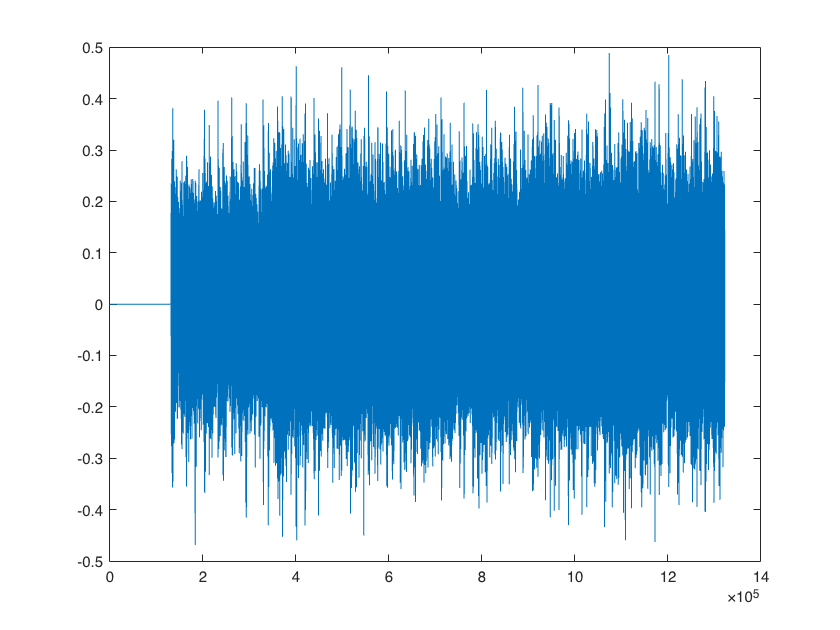

plot(cleanSig);

### Evaluate

exp_name = 'test';
data = result_snr;

Unrecognized function or variable 'result_snr'.

filename = './results.txt';
evaluate(filename, exp_name, result_snr, x, xhat)

devDataPath = "/Users/noelalben/Desktop/DSP_finalProject/music-denoising-spring2023/data/dev";

devDataFolders = ls(devDataPath);
% For unix and macbook
devDataFolders = strsplit(devDataFolders)

devDataFolders = 1×201 cell array
    {'000'}    {'013'}    {'026'}    {'039'}    {'052'}    {'065'}    {'078'}    {'091'}    {'104'}    {'117'}    {'130'}    {'143'}    {'156'}    {'169'}    {'182'}    {'195'}    {'001'}    {'014'}    {'027'}    {'040'}    {'053'}    {'066'}    {'079'}    {'092'}    {'105'}    {'118'}    {'131'}    {'144'}    {'157'}    {'170'}    {'183'}    {'196'}    {'002'}    {'015'}    {'028'}    {'041'}    {'054'}    {'067'}    {'080'}    {'093'}    {'106'}    {'119'}    {'132'}    {'145'}    {'158'}    {'171'}    {'184'}    {'197'}    {'003'}    {'016'}    {'029'}    {'042'}    {'055'}    {'068'}    {'081'}    {'094'}    {'107'}    {'120'}    {'133'}    {'146'}    {'159'}    {'172'}    {'185'}    {'198'}    {'004'}    {'017'}    {'030'}    {'043'}    {'056'}    {'069'}    {'082'}    {'095'}    {'108'}    {'121'}    {'134'}    {'147'}    {'160'}    {'173'}    {'186'}    {'199'}    {'005'}    {'018'}    {'031'}    {'044'}    {'057'}    {'070'}    {'083'}    {'096


nDevSamples = size(devDataFolders, 2)-1;

initSnr = NaN(nDevSamples, 1);
finalSnr = NaN(nDevSamples, 1);

for i = 1:nDevSamples
    noisyFile = fullfile(devDataPath, devDataFolders(i), "noisy.wav");
    cleanFile = fullfile(devDataPath, devDataFolders(i), "clean.wav");

    [noisySig, fs] = audioread(noisyFile);
    [cleanSig, fsc] = audioread(cleanFile);

    assert(fs == fsc);

    estimSig = denoise(noisySig, fs);
    
    initSnr(i) = computeSnr(cleanSig, noisySig);
    disp(initSnr(i))
    finalSnr(i) = computeSnr(cleanSig, estimSig);    
end

deltaSnr = finalSnr - initSnr;

fprintf("Input SNR (dB)");
descStats(initSnr);

fprintf("Output SNR (dB)");
descStats(finalSnr);

fprintf("Change in SNR (dB)");
descStats(deltaSnr);